# System Objects for Classification and Code Generation

This example shows how to generate C code from a MATLAB® System object™ that classifies images of digits by using a trained classification model. This example also shows how to use the System object for classification in Simulink®. The benefit of using System objects over MATLAB function is that System objects are more appropriate for processing large amounts of streaming data. For more details, see [What Are System Objects?](docid:matlab_prog.btpzufx-1).

This example is based on [C Code Generation for Image Classifier](docid:stats_ug.example-ex31452691), which is an alternative workflow to [Digit Classification Using HOG Features](docid:vision_ug.example-HOGDigitClassificationExample).

## Load Data

Load the `digitimages`.

load digitimages.mat

`images` is a 28-by-28-by-3000 array of `uint16` integers. Each page is a raster image of a digit. Each element is a pixel intensity. Corresponding labels are in the 3000-by-1 numeric vector `Y`. For more details, enter `Description` at the command line.

Store the number of observations and the number of predictor variables. Create a data partition that specifies to hold out 20% of the data. Extract training and test set indices from the data partition.

rng(1); % For reproducibility
n = size(images,3);
p = numel(images(:,:,1));
cvp = cvpartition(n,'Holdout',0.20);
idxTrn = training(cvp);
idxTest = test(cvp);

## Rescale Data

Rescale the pixel intensities so that they range in the interval [0,1] within each image. Specifically, suppose $p_{ij}$ is pixel intensity $j$ within image $i$. For image $i$, rescale all of its pixel intensities by using this formula:


$$\hat p_{ij} = \frac{p_{ij} - \min_j(p_{ij})}{\max_j(p_{ij}) -
\min_j(p_{ij})}.$$


X = double(images);

for i = 1:n
    minX = min(min(X(:,:,i)));
    maxX = max(max(X(:,:,i)));
    X(:,:,i) = (X(:,:,i) - minX)/(maxX - minX);
end

## Reshape Data

For code generation, the predictor data for training must be in a table of numeric variables or a numeric matrix.

Reshape the data to a matrix such that predictor variables correspond to columns and images correspond to rows. Because `reshape` takes elements column-wise, transpose its result.

X = reshape(X,[p,n])';

## Train and Optimize Classification Models

Cross-validate an ECOC model of SVM binary learners and a random forest based on the training observations. Use 5-fold cross-validation.

For the ECOC model, specify predictor standardization and optimize classification error over the ECOC coding design and the SVM box constraint. Explore all combinations of these values:

- For the ECOC coding design, use one-versus-one and one-versus-all.

- For the SVM box constraint, use three logarithmically spaced values from 0.1 to 100 each. For all models, store the 5-fold cross-validated misclassification rates.

coding = {'onevsone' 'onevsall'};
boxconstraint = logspace(-1,2,3);
cvLossECOC = nan(numel(coding),numel(boxconstraint)); % For preallocation

for i = 1:numel(coding)
    for j = 1:numel(boxconstraint)
        t = templateSVM('BoxConstraint',boxconstraint(j),'Standardize',true);
        CVMdl = fitcecoc(X(idxTrn,:),Y(idxTrn),'Learners',t,'KFold',5,...
            'Coding',coding{i});
        cvLossECOC(i,j) = kfoldLoss(CVMdl);
        fprintf('cvLossECOC = %f for model using %s coding and box constraint=%f\n',...
            cvLossECOC(i,j),coding{i},boxconstraint(j))
    end
end

For the random forest, vary the maximum number of splits by using the values in the sequence  $\{3^2, 3^3,...,3^m\}$. m is such that $3^m$ is no greater than *n* - 1. To reproduce random predictor selections, specify `'Reproducible',true`.

n = size(X,1);
m = floor(log(n - 1)/log(3));
maxNumSplits = 3.^(2:m);
cvLossRF = nan(numel(maxNumSplits));
for i = 1:numel(maxNumSplits)
    t = templateTree('MaxNumSplits',maxNumSplits(i),'Reproducible',true);
    CVMdl = fitcensemble(X(idxTrn,:),Y(idxTrn),'Method','bag','Learners',t,...
        'KFold',5);
    cvLossRF(i) = kfoldLoss(CVMdl);
    fprintf('cvLossRF = %f for model using %d as the maximum number of splits\n',...
        cvLossRF(i),maxNumSplits(i))
end

For each algorithm, determine the hyperparameter indices that yield the minimal misclassification rates.

minCVLossECOC = min(cvLossECOC(:))
linIdx = find(cvLossECOC == minCVLossECOC,1);
[bestI,bestJ] = ind2sub(size(cvLossECOC),linIdx);
bestCoding = coding{bestI}
bestBoxConstraint = boxconstraint(bestJ)
minCVLossRF = min(cvLossRF(:))
linIdx = find(cvLossRF == minCVLossRF,1);
[bestI,bestJ] = ind2sub(size(cvLossRF),linIdx);
bestMNS = maxNumSplits(bestI)

The random forest achieves a smaller cross-validated misclassification rate.

Train an ECOC model and a random forest using the training data. Supply the optimal hyperparameter combinations.

t = templateSVM('BoxConstraint',bestBoxConstraint,'Standardize',true);
MdlECOC = fitcecoc(X(idxTrn,:),Y(idxTrn),'Learners',t,'Coding',bestCoding);
t = templateTree('MaxNumSplits',bestMNS);
MdlRF = fitcensemble(X(idxTrn,:),Y(idxTrn),'Method','bag','Learners',t);

Create a variable for the test sample images and use the trained models to predict test sample labels.

testImages = X(idxTest,:);
testLabelsECOC = predict(MdlECOC,testImages);
testLabelsRF = predict(MdlRF,testImages);

## Save Classification Model to Disk

`MdlECOC` and `MdlRF` are predictive classification models, but you must prepare them for code generation. Save `MdlECOC` and `MdlRF` to your present working folder using `saveLearnerForCoder`.

saveLearnerForCoder(MdlECOC,'DigitImagesECOC');
saveLearnerForCoder(MdlRF,'DigitImagesRF');

## Create System Object for Prediction

Create two System objects, one for the ECOC model and the other for the random forest, that:

- Load the previously saved trained model by using `loadLearnerForCoder`.

- Make sequential predictions by the `step` method.

- Enforce no size changes to the input data.

- Enforce double-precision, scalar output.

type ECOCClassifier.m % Display contents of ECOCClassifier.m file
type RFClassifier.m % Display contents of RFClassifier.m file

**Note:** If you click the button located in the upper-right section of this page and open this example in MATLAB®, then MATLAB® opens the example folder. This folder includes the files used in this example.

For System object basic requirements, see [Define Basic System Objects](docid:matlab_prog.bs4mxcb-1).

## Define Prediction Functions for Code Generation

Define two MATLAB functions called `predictDigitECOCSO.m` and `predictDigitRFSO.m`. The functions:

- Include the code generation directive `%#codegen`.

- Accept image data commensurate with `X`.

- Predict labels using the `ECOCClassifier` and `RFClassifier` System objects, respectively.

- Return predicted labels.

type predictDigitECOCSO.m % Display contents of predictDigitECOCSO.m file
type predictDigitRFSO.m % Display contents of predictDigitRFSO.m file

## Compile MATLAB Function to MEX File

Compile the prediction function that achieves better test-sample accuracy to a MEX file by using `codegen`. Specify the test set images by using the `-args` argument.

if(minCVLossECOC <= minCVLossRF)
    codegen predictDigitECOCSO -args testImages    
else   
    codegen predictDigitRFSO -args testImages
end

Verify that the generated MEX file produces the same predictions as the MATLAB function.

if(minCVLossECOC <= minCVLossRF)
    mexLabels = predictDigitECOCSO_mex(testImages);
    verifyMEX = sum(mexLabels == testLabelsECOC) == numel(testLabelsECOC)    
else   
    mexLabels = predictDigitRFSO_mex(testImages);
    verifyMEX = sum(mexLabels == testLabelsRF) == numel(testLabelsRF)    
end

`verifyMEX` is `1`, which indicates that the predictions made by the generated MEX file and the corresponding MATLAB function are the same.

## Predict Labels by Using System Objects in Simulink

Create a video file that displays the test-set images frame-by-frame.

v = VideoWriter('testImages.avi','Uncompressed AVI');
v.FrameRate = 1;
open(v);
dim = sqrt(p)*[1 1];
for j = 1:size(testImages,1)
    writeVideo(v,reshape(testImages(j,:),dim));
end
close(v);

Define a function called `scalePixelIntensities.m` that converts RGB images to grayscale, and then scales the resulting pixel intensities so that their values are in the interval [0,1].

type scalePixelIntensities.m % Display contents of scalePixelIntensities.m file

Load the Simulink® model `slexClassifyAndDisplayDigitImages.slx`.

SimMdlName = 'slexClassifyAndDisplayDigitImages';
open_system(SimMdlName);

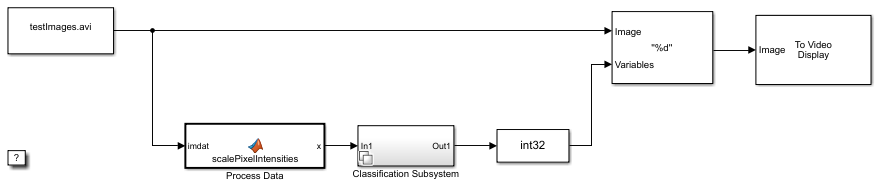

The figure displays the Simulink® model. At the beginning of simulation, the From Multimedia File block loads the video file of the test-set images. For each image in the video:

- The From Multimedia File block converts and outputs the image to a 28-by-28 matrix of pixel intensities.

- The Process Data block scales the pixel intensities by using `scalePixelIntensities.m`, and outputs a 1-by-784 vector of scaled intensities.

- The Classification Subsystem block predicts labels given the processed image data. The block chooses the System object that minimizes classification error. In this case, the block chooses the random forest. The block outputs a double-precision scalar label.

- The Data Type Conversion block converts the label to an `int32` scalar.

- The Insert Text block embeds the predicted label on the current frame.

- The To Video Display block displays the annotated frame.

Simulate the model.

sim(SimMdlName)

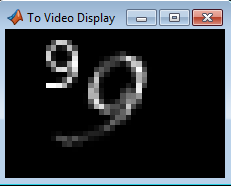

The model displays all 600 test-set images and its prediction quickly. The last image remains in the video display. You can generate predictions and display them with corresponding images one-by-one by clicking the **Step Forward** button instead.

If you also have a Simulink® Coder™ license, then you can generate C code from `slexClassifyAndDisplayDigitImages.slx` in Simulink® or from the command line using [`slbuild`](docid:simulink_ref.btvn60i). For more details, see [Generate C Code for a Model](docid:rtw_gs.btyj0uu).

*Copyright 2017 The MathWorks, Inc.*